# cargar_datos_shimmer

Read a text file generated by the shimmer sensors. 

## Syntax

`[medicion]= cargar_datos_shimmer(file,idname)`  

## Description

`[medicion]= cargar_datos_shimmer(file,idname)` `file` is the name of the file, and `idname` an identifier of the data structure where the data will be stored. 

The data structure that the function creates has the form:

 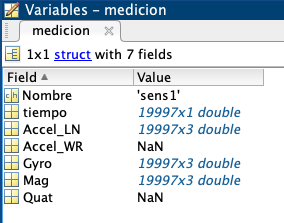  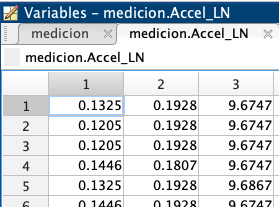

## Examples

% Lectura de un archivo:
medicion=cargar_datos_shimmer('sh38aa.csv','sens1')

medicion = struct with fields:
      Nombre: 'sens1'
      tiempo: [19997×1 double]
    Accel_LN: [19997×3 double]
    Accel_WR: NaN
        Gyro: [19997×3 double]
         Mag: [19997×3 double]
        Quat: NaN


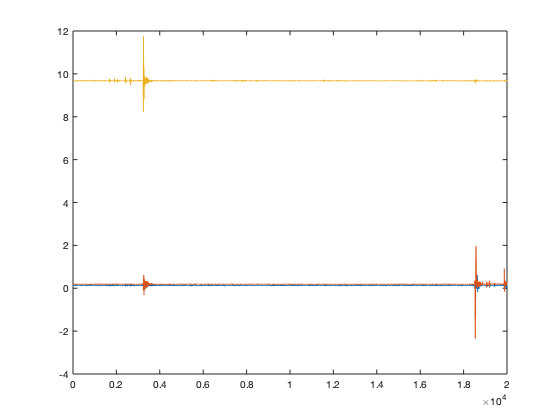


% Representa loa acelerometros:
plot(medicion.Accel_LN)

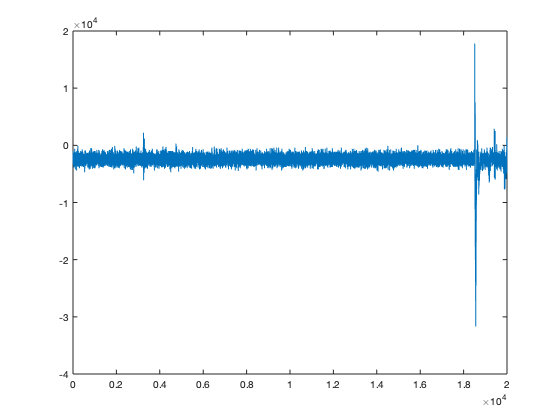

% El giroscopio en Y:
plot(medicion.Gyro(:,2))